clear all

### Constants

global m g h kp hn0 hp0 kn Eg Ep En Pi
m0 = 100; %                   [kg]      unloaded mass
m1 = m0 + 250; %              [Kg]      loaded mass
g = 9.81; %                   [m/s^2]   gravity acceleration

Des_Long = -100E-3;%          [m]       desired initial elongation of the positive spring
kp = round(-m1*g/Des_Long)%        [N/m]     stiffness of the main spring

kp = 34335

stroke = 0.1; %               [m]       desired stroke in each direction 
h = [Des_Long-stroke:0.001:Des_Long+stroke]; %range of heights 

## Variables

hn0 = -0.101;%initial position negative spring
%Default hn0 = -0.1
hp0 = -0.001;%initial position positive spring
%Default hp0 = 0
m = 350 ;%mass that is on the system
%Default m = 350
r = 0.9 ;% ration between kn kp

kn = - r*kp; %relation between the positive and negative stiffness
computeEnergy(); %computing the energy equations

## Resulting Energy Curves

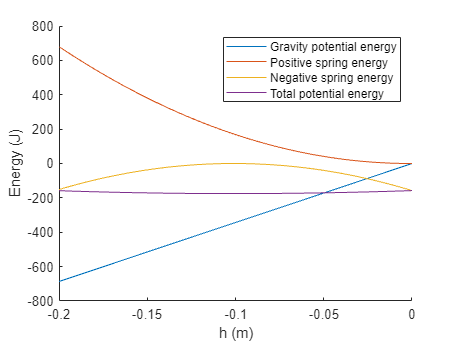

figure()
clf;
hold on
plot(h,Eg)
plot(h,Ep)
plot(h,En)
plot(h,Pi)
legend('Gravity potential energy','Positive spring energy','Negative spring energy',"Total potential energy")
xlabel('h (m)')
ylabel('Energy (J)')

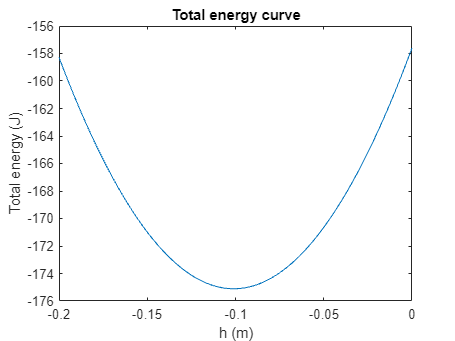


figure()
clf;
plot(h,Pi)
xlabel('h (m)')
ylabel('Total energy (J)')
title('Total energy curve')

[C, I] = min(Pi);
equilibriumpos = h(I)

equilibriumpos = -0.1010

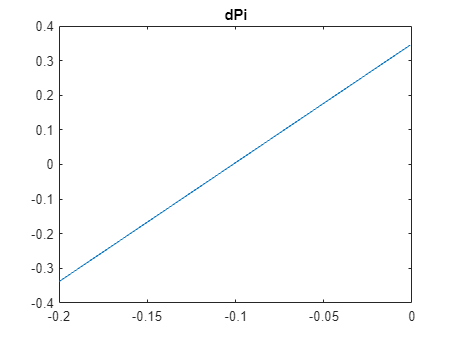

figure()
clf;
dPi = diff(Pi);
plot(h(1:length(h)-1),dPi)
title('dPi')

## Resulting potential energy curves vs relation kp-kn

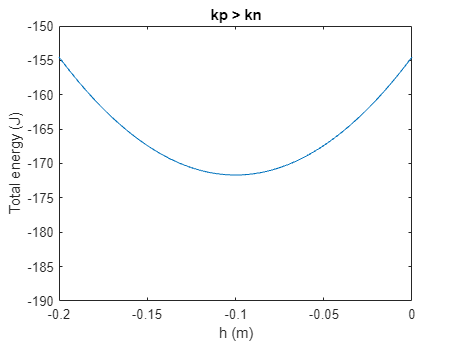

hn0 = -0.1;
hp0 = 0;
m = 350;

lims = [-190;-150];

figure() % case kp > kn
kn = - 0.9*kp;
computeEnergy(); %computing the energy equations
plot(h,Pi)
xlabel('h (m)')
ylabel('Total energy (J)')
title("kp > kn")
ylim(lims)

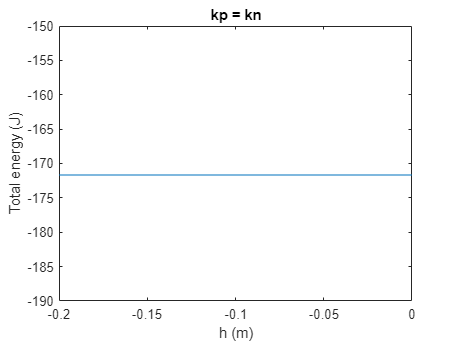


figure() % case kp = kn
kn = -kp;
computeEnergy(); %computing the energy equations
plot(h,Pi)
xlabel('h (m)')
ylabel('Total energy (J)')
title("kp = kn")
ylim(lims)

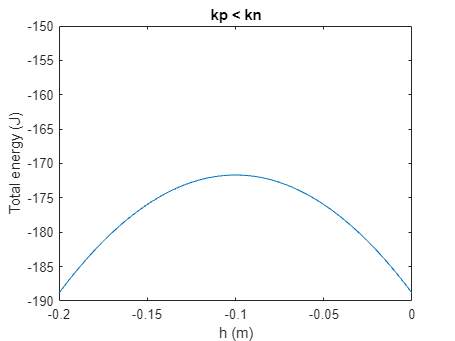


figure() % case kp < kn
kn = - 1.1*kp;
computeEnergy(); %computing the energy equations
plot(h,Pi)
xlabel('h (m)')
ylabel('Total energy (J)')
title("kp < kn")
ylim(lims)

Functions

function computeEnergy()
    global m g h kp hn0 hp0 kn Eg Ep En Pi
    Eg = m*g*h;
    Ep = 0.5*kp*(h-hp0).^2;
    En = 0.5*kn*(h-hn0).^2;
    Pi = Ep + En + Eg;
end